# Linear Control Design II - Group Work Problem Module 2

## Description

In Figure 1 an electro-mechanical system is illustrated. The mechanical part is composed of a flexible structure buit by three masses interconnected by flexible beams. The electrical part is composed of a pair of electromagnets. The lateral movements of the lower mass is coupled to the pair of electromagnets by means of the electromagnetic forces generated in the small gap illustrated in Figure 2. It means there is no mechanical contact between the two parts. The main goal is: a) to build an electro-mechanical model based on simplifying assumptions; b) to build a mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday; c) to build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t),\,\,x_2(t),\,\,x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$; d) investigate the vibrations of the structure when different initial conditions and inputs are present.

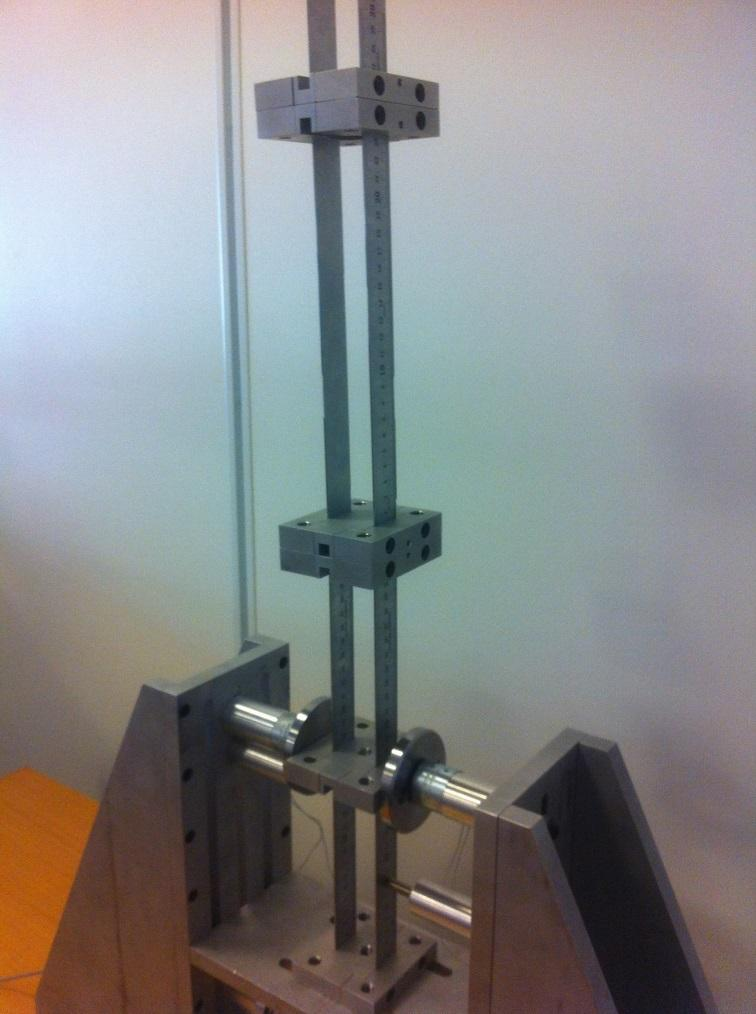


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


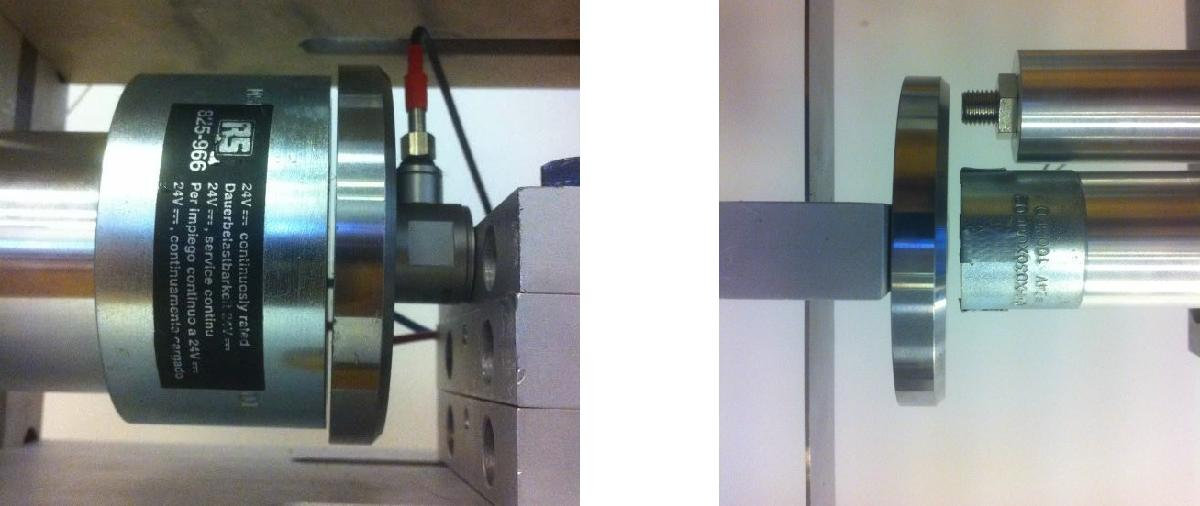


$$(a)\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad (b)$$



$$Figure\,2:\,The\,electro parts:\,(a)\,one\,single\,electromagnet\,and\,the\,gap\,where\,the\\ electromagnetic\,force\,will\,be\,generated\,by\,the\,input\,voltage\,u(t);\,(b)\,electromagnetic\\ actuator\,and\,eddy-current\,displacement\,sensor\,using\,to\,control\,and\,to\,measure\,the\\ lateral\,movements\,of\,the\,lower\,mass.$$


For the simulations the following parameters should be used.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

R = 148.2;
L = 800e-3; % [H]

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

Ki5 = 22.4;
Ks5 = -313.6;

Ki3 = 37.33;
Ks3 = -871.11;

Ki2 = 56;
Ks2 = -1.96e3;

Ki1 = 112;
Ks1 = -7.84e3;

Where $Ki\#$ indicates the magnitude of the linearized force dependent on current change when the air gap $s_0$=$\#$ mm.

**Problem 1**

Build an electro-mechanical model based on simplifying assumptions.

**Solution:**

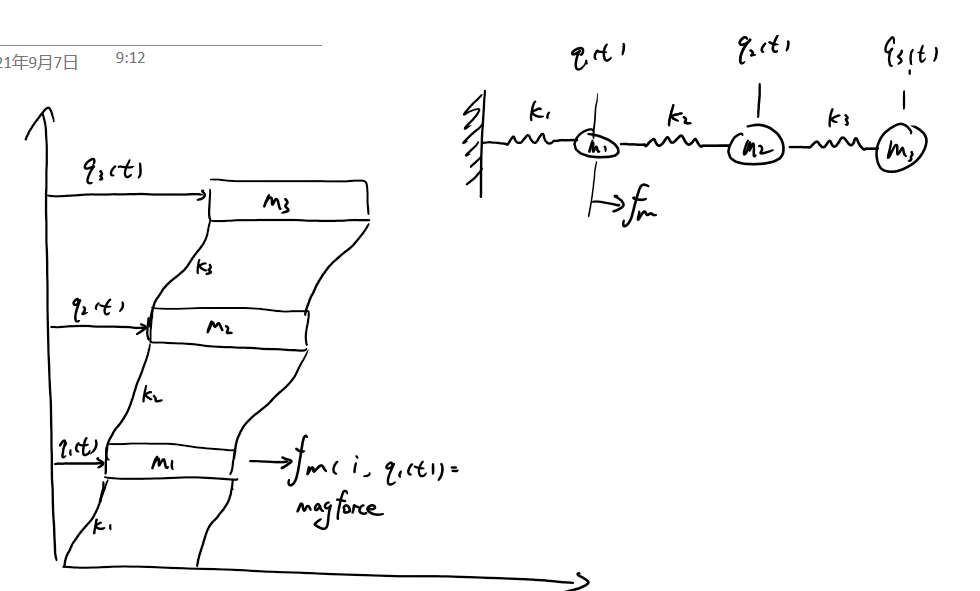


$$Figure\,3:\,Mechanical\,and\,electrical\,models$$


**Problem 2**

Build the mathematical model for describing the dynamics of the mechanical and electro-magnetic parts  based on first principles postulated by Newton, Ampere, Ohm, Faraday, based on the electro-mechanical model and simplifying assumptions done in problem 1.Use as main variables the  three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.

**Solution:**

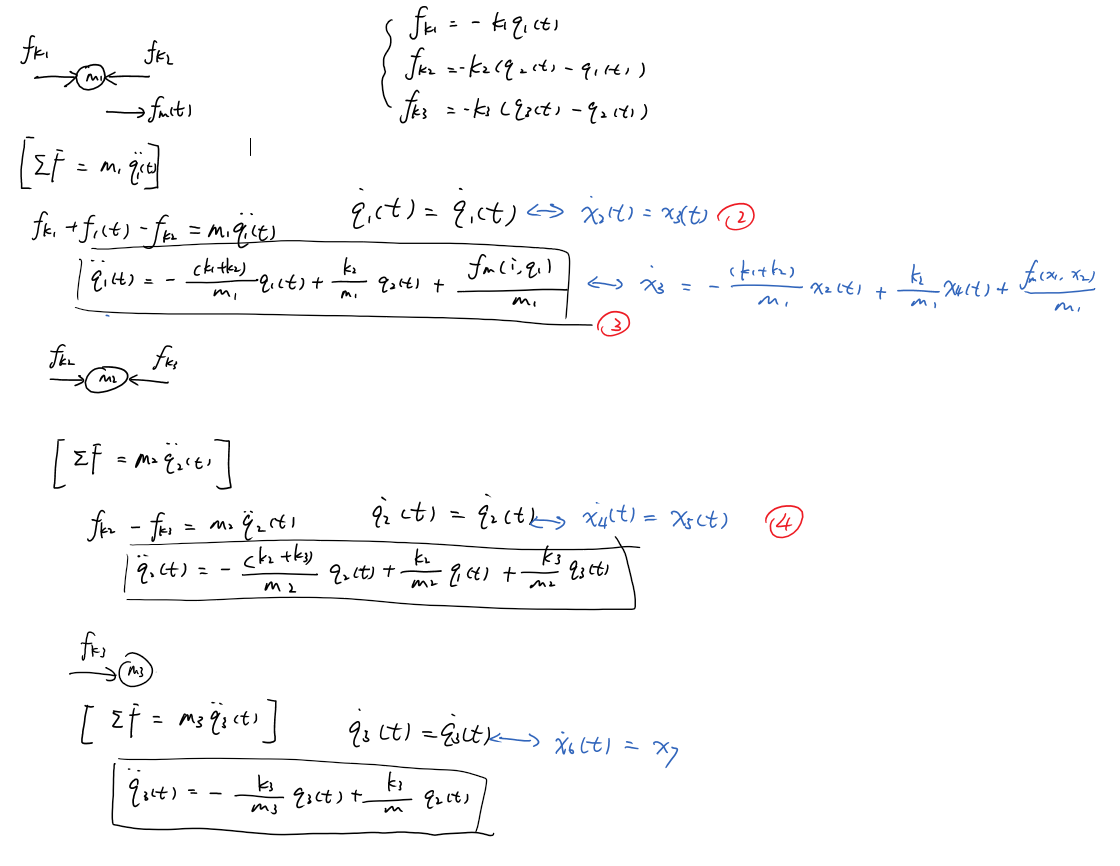


$$Figure\,4:\,The\,global\,mathematical\,model\,of\,mechanical\,system$$


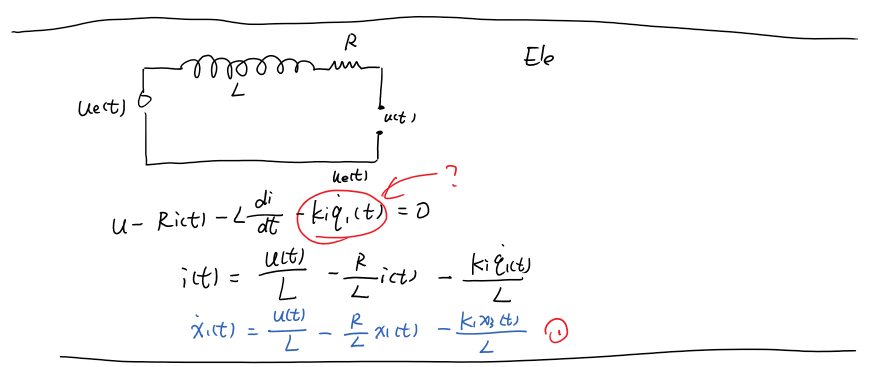


$$Figure\,4:\,The\,global\,mathematical\,model\,of\,electrical\,system$$


**Problem 3**

Build a simulik model to describe the coupled dynamics between the lateral movements of the three masses $x_1(t)$, $x_2(t)$, $x_3(t)$ and the current $i(t)$ induced in the coils depending on the electrical potential $u(t)$.  

**Solution:**

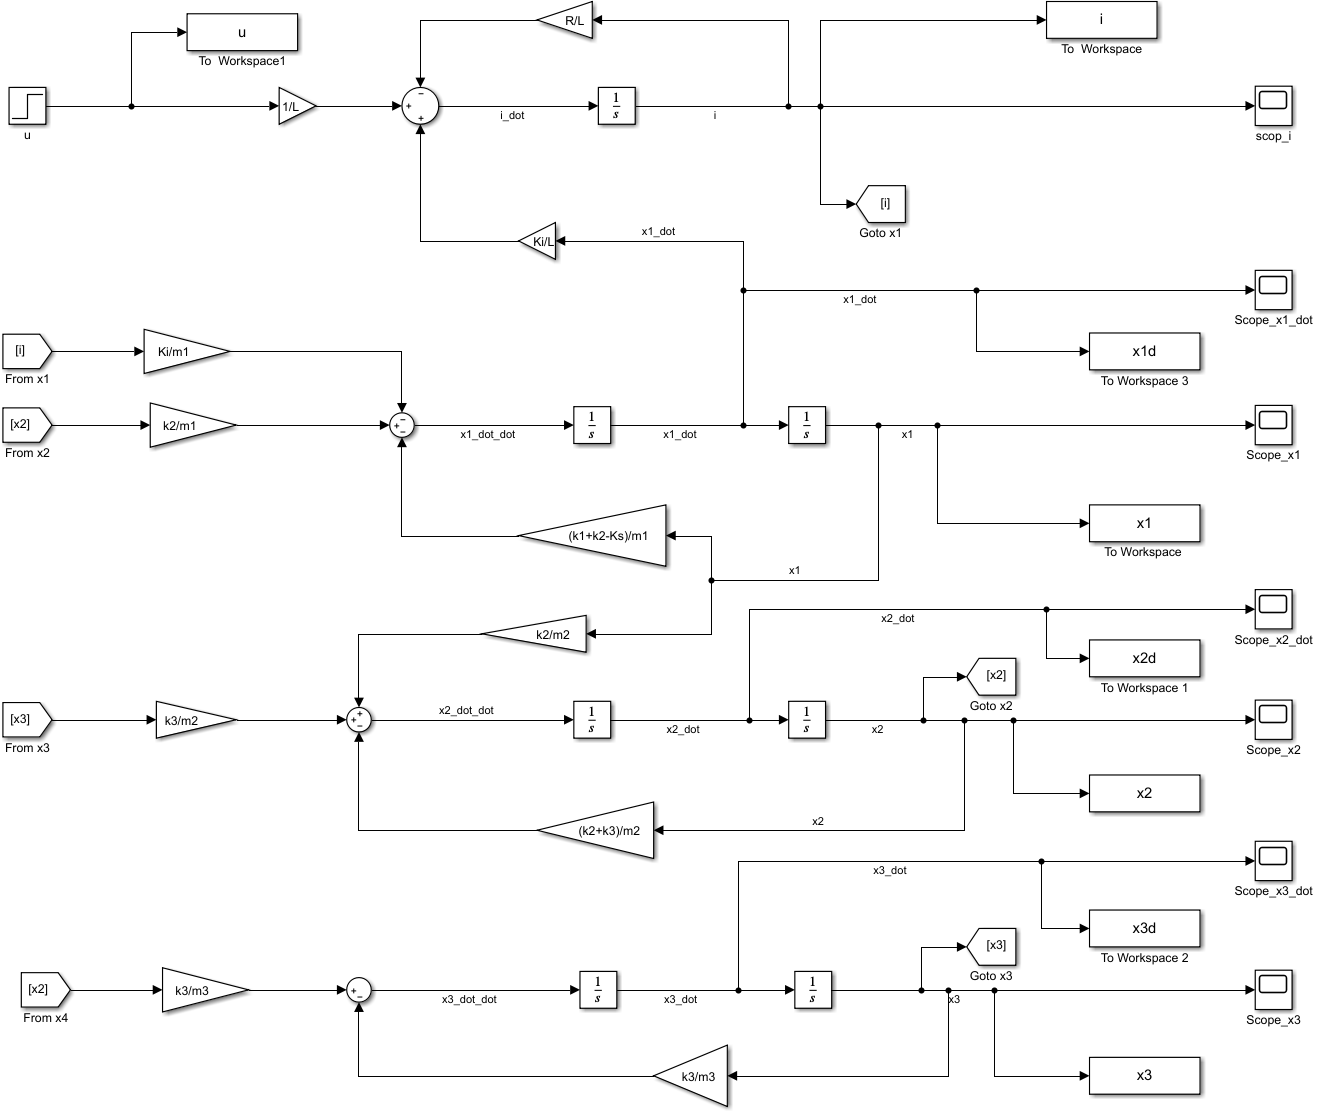


$$Figure\,5:\,The\,simulink\,diagram\,used\,to\,simulate\,the\,coupled\,dynamics\\ between\,the\,lateral\,movements\,of\,the\,three\,masses\,x_1(t),\,x_2(t),\,x_3(t)\,and\\ the\,current\,i(t)\,induced\,in\,the\,coils\,depending\,on\,the\,electrical\,potential\,u(t)$$


**Problem 4**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results.

**Solution:**

**4a) **Behavior of system when $s_0=5mm$

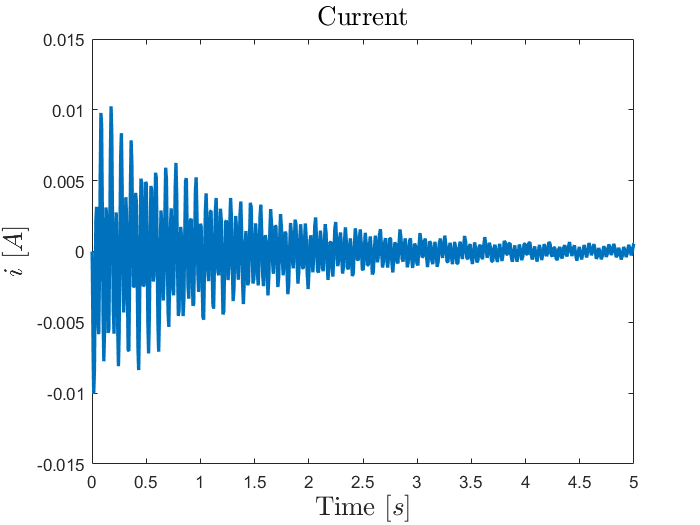

% Your solution goes here:

Ki = Ki5;
Ks = Ks5;

% initial conditions
x_0 = [0 0.001 0 0 0 0 0]'; 
%[1 2   3     4   5     6     7  ]
%[i x1 x1_dot x2 x2_dot x3 x3_dot]
u_0 = 0;

% Simulation
sim("myEmagModel");
%sim("electroMagnetModel");

% Plots
time = i.time;

% i
figure
plot(time,i.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Current',"FontSize",16, 'Interpreter','latex');

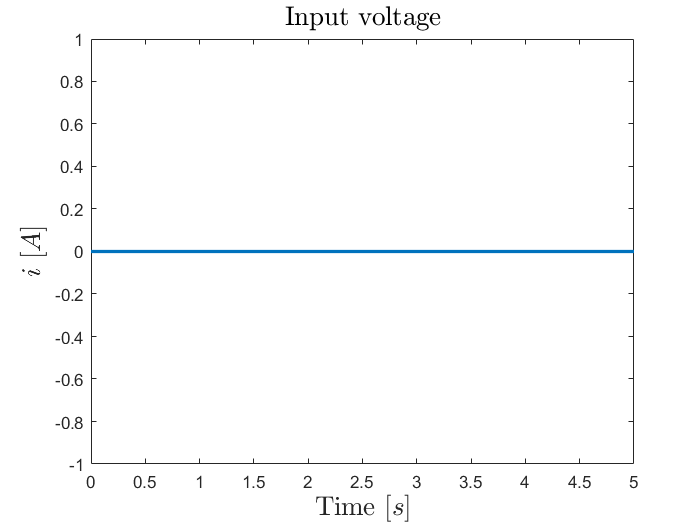


% u
figure
plot(time,u.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Input voltage',"FontSize",16, 'Interpreter','latex');

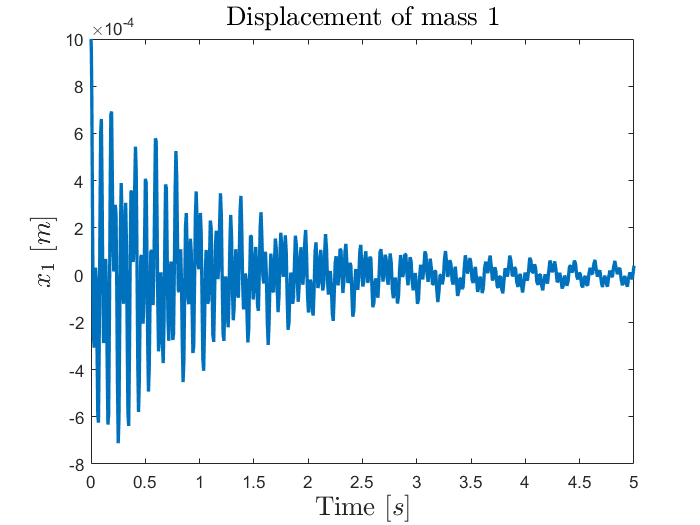


% x1
figure
plot(time,x1.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_1$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 1',"FontSize",16, 'Interpreter','latex');

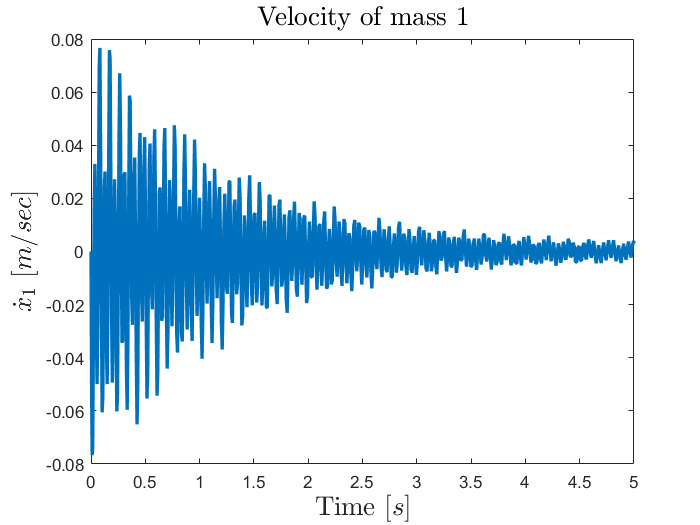


%x1_dot
figure
plot(time,x1d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 1',"FontSize",16, 'Interpreter','latex');

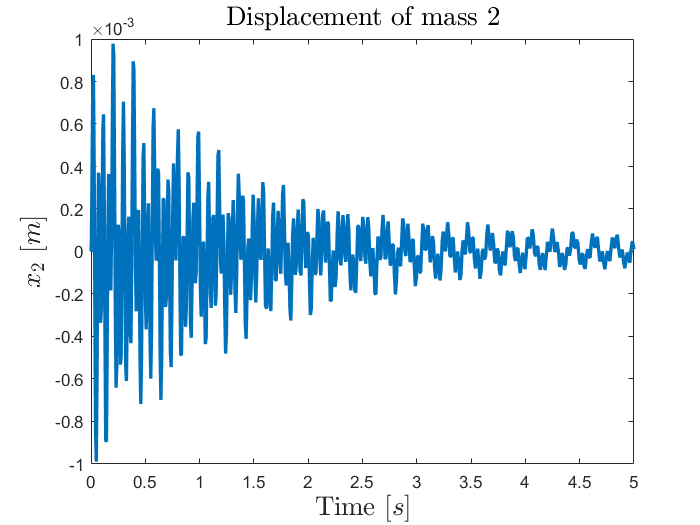


%x2
figure
plot(time,x2.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_2$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 2',"FontSize",16, 'Interpreter','latex');

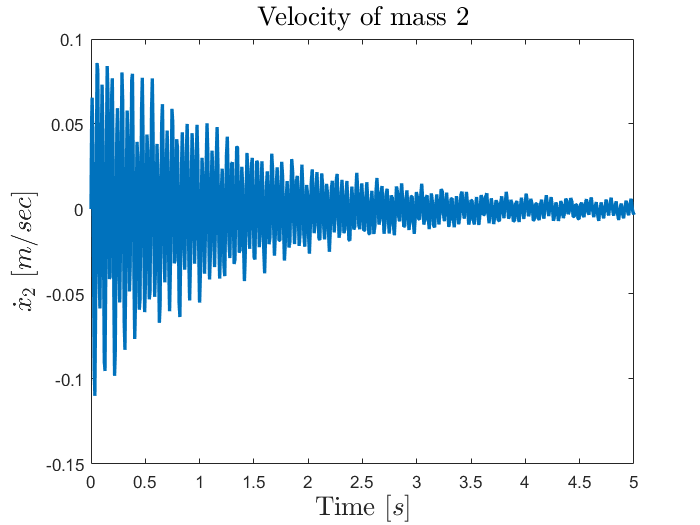


%x2_dot
figure
plot(time,x2d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 2',"FontSize",16, 'Interpreter','latex');

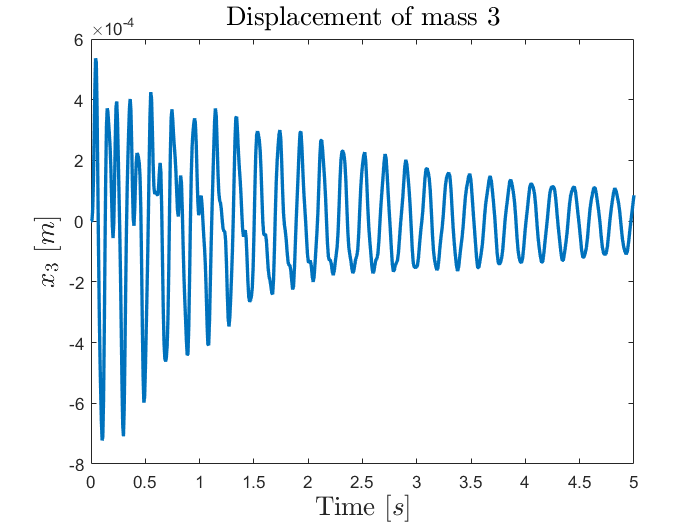


%x3
figure
plot(time,x3.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_3$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 3',"FontSize",16, 'Interpreter','latex');

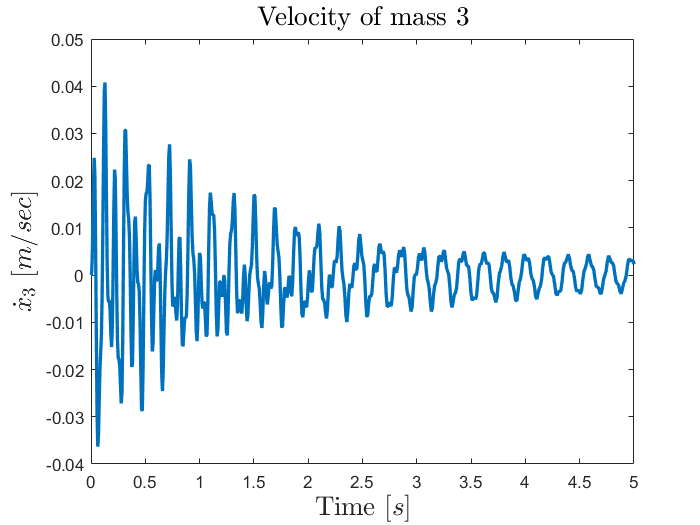


%x3_dot
figure
plot(time,x3d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 3',"FontSize",16, 'Interpreter','latex');

**4b)** Behavior of system when $s_0=3mm$

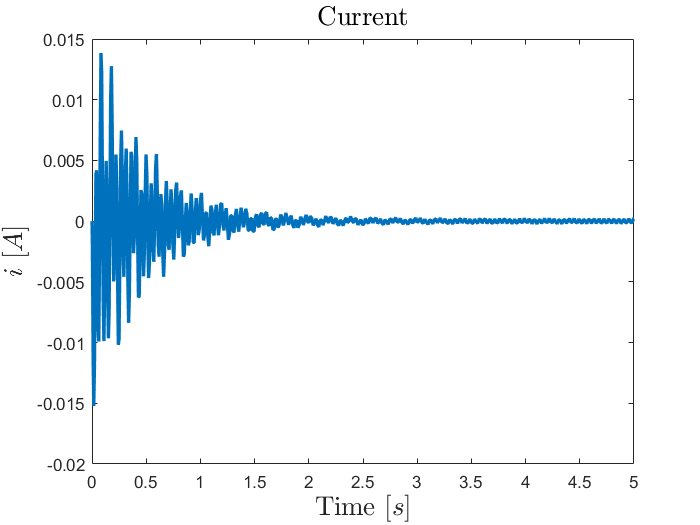

% Air gap condition
Ki = Ki3;
Ks = Ks3;

% initial conditions
x_0 = [0 0.001 0 0 0 0 0]'; 
%[1 2   3     4   5     6     7  ]
%[i x1 x1_dot x2 x2_dot x3 x3_dot]
u_0 = 0;

% Simulation
sim("myEmagModel");
%sim("electroMagnetModel");

% Plots
time = i.time;

% i
figure
plot(time,i.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Current',"FontSize",16, 'Interpreter','latex');


% u
figure
plot(time,u.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Input voltage',"FontSize",16, 'Interpreter','latex');

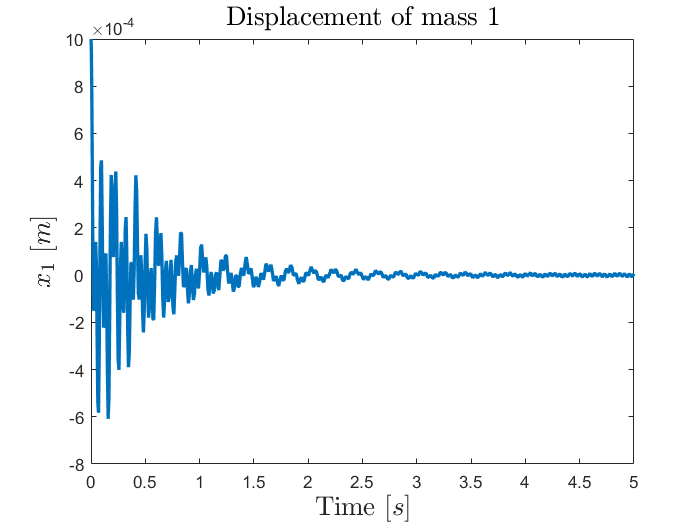


% x1
figure
plot(time,x1.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_1$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 1',"FontSize",16, 'Interpreter','latex');

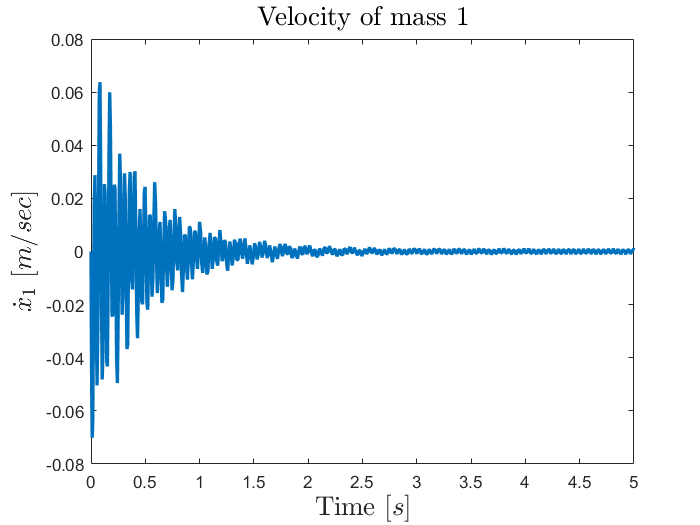


%x1_dot
figure
plot(time,x1d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 1',"FontSize",16, 'Interpreter','latex');

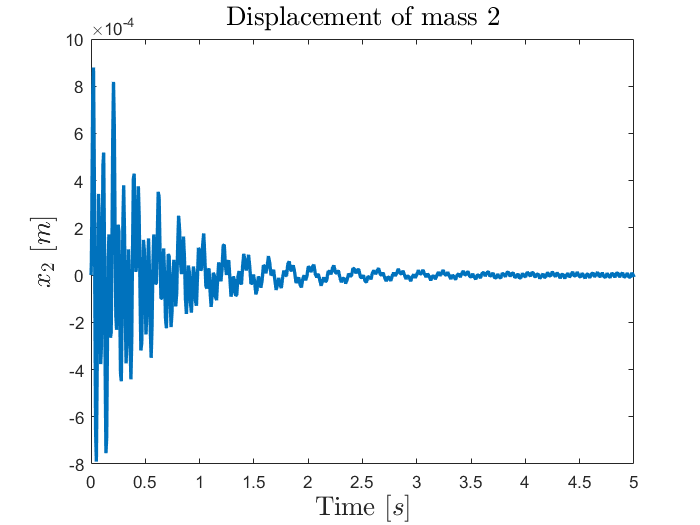


%x2
figure
plot(time,x2.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_2$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 2',"FontSize",16, 'Interpreter','latex');

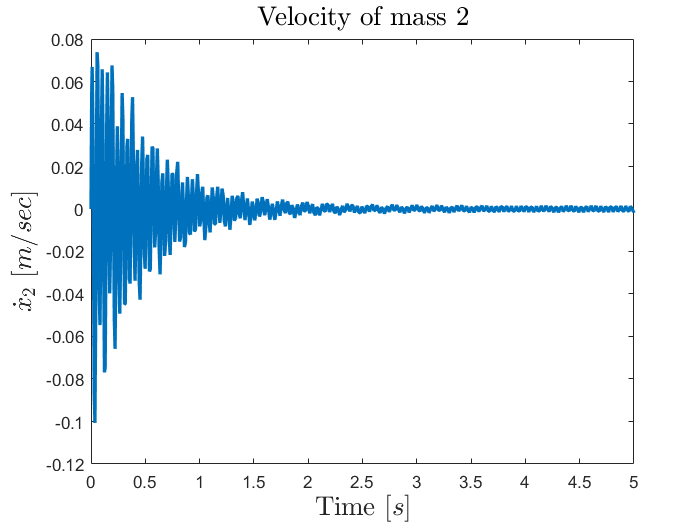


%x2_dot
figure
plot(time,x2d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 2',"FontSize",16, 'Interpreter','latex');

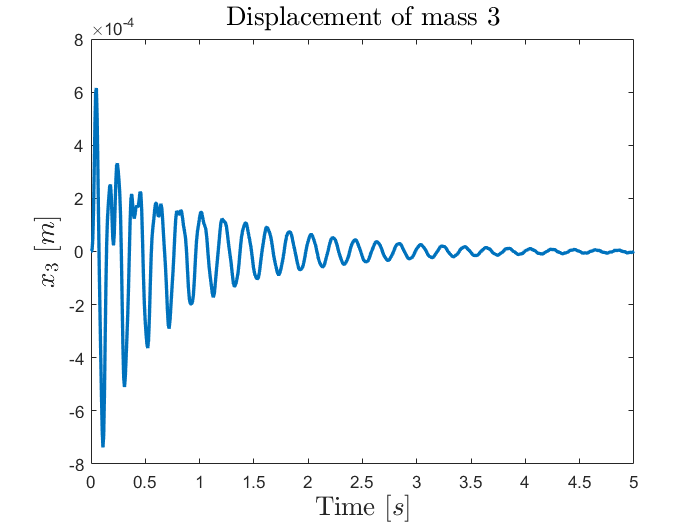


%x3
figure
plot(time,x3.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_3$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 3',"FontSize",16, 'Interpreter','latex');

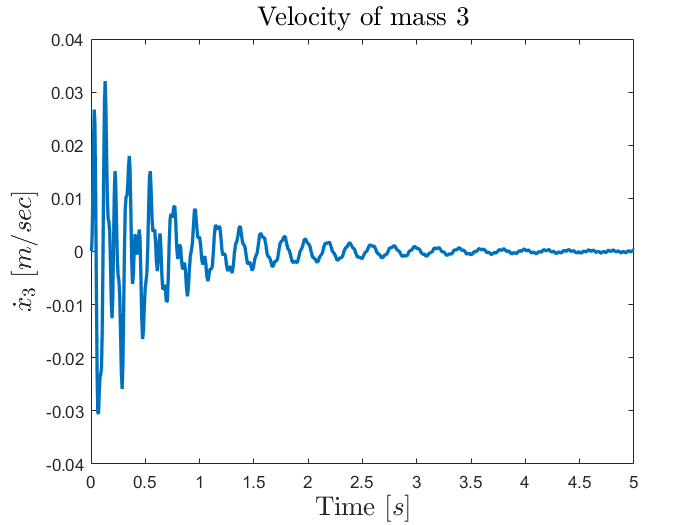


%x3_dot
figure
plot(time,x3d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 3',"FontSize",16, 'Interpreter','latex');

**4c)** Behavior of system when $s_0=1mm$

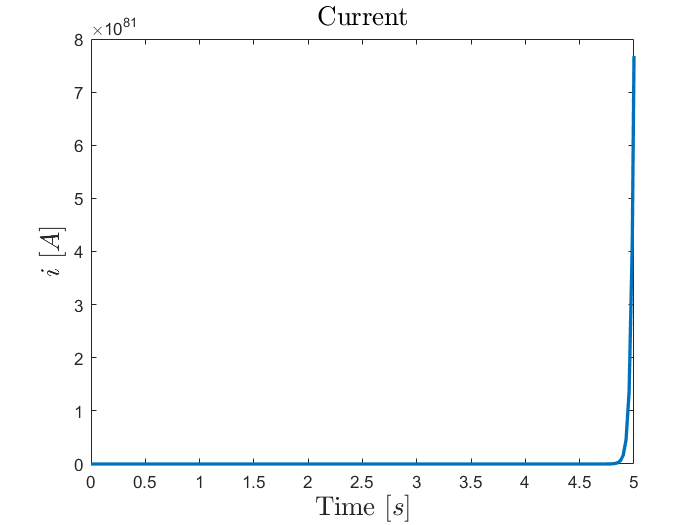

% Air gap condition
Ki = Ki1;
Ks = Ks1;

% initial conditions
x_0 = [0 0.001 0 0 0 0 0]'; 
%[1 2   3     4   5     6     7  ]
%[i x1 x1_dot x2 x2_dot x3 x3_dot]
u_0 = 0;

% Simulation
sim("myEmagModel");

% Plots
time = i.time;

% i
figure
plot(time,i.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Current',"FontSize",16, 'Interpreter','latex');


% u
figure
plot(time,u.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Input voltage',"FontSize",16, 'Interpreter','latex');

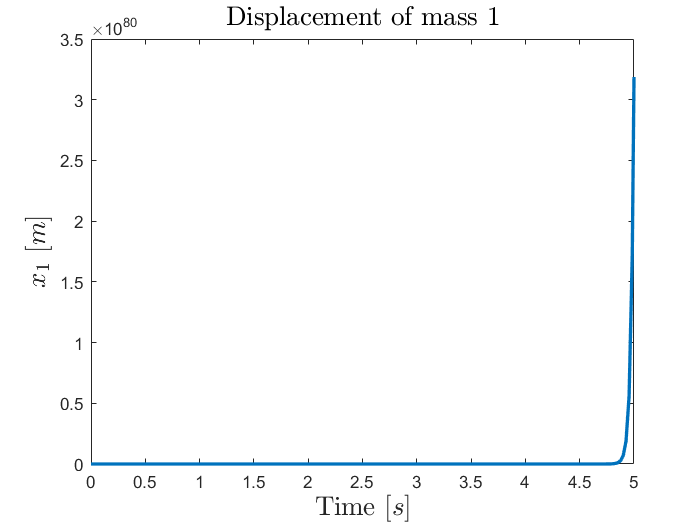


% x1
figure
plot(time,x1.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_1$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 1',"FontSize",16, 'Interpreter','latex');

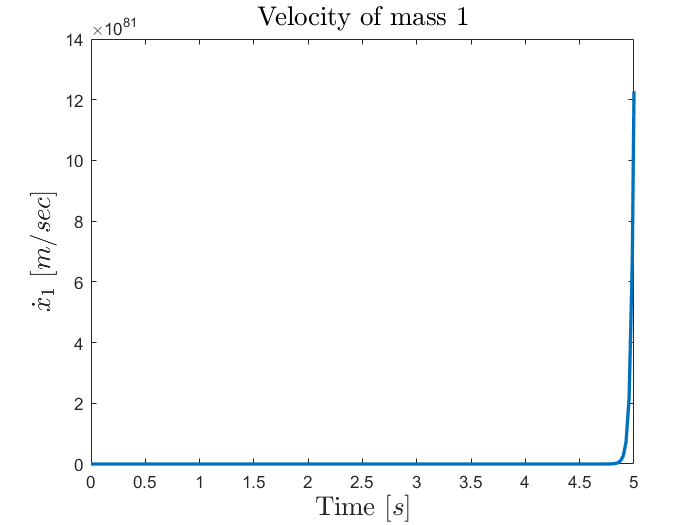


%x1_dot
figure
plot(time,x1d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 1',"FontSize",16, 'Interpreter','latex');

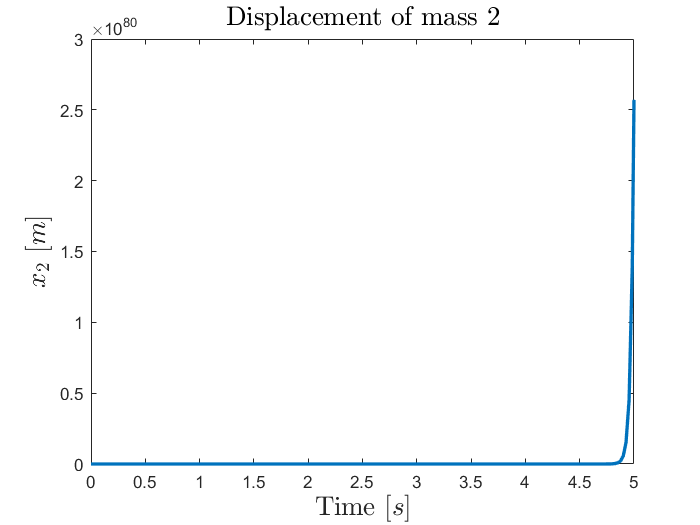


%x2
figure
plot(time,x2.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_2$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 2',"FontSize",16, 'Interpreter','latex');

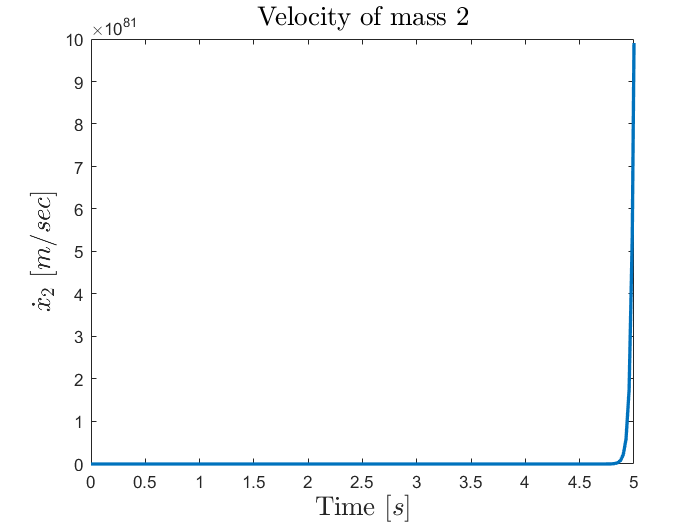


%x2_dot
figure
plot(time,x2d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 2',"FontSize",16, 'Interpreter','latex');

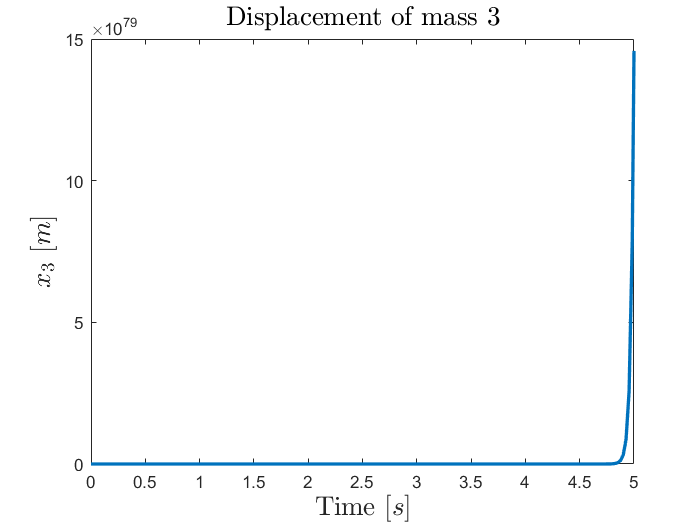


%x3
figure
plot(time,x3.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_3$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 3',"FontSize",16, 'Interpreter','latex');

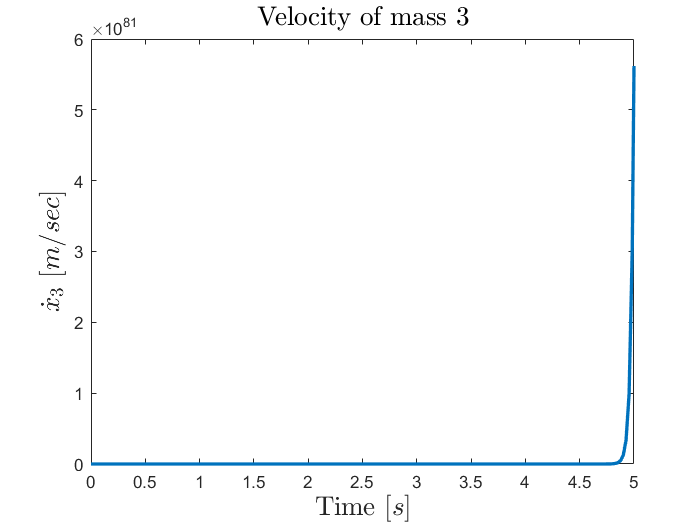


%x3_dot
figure
plot(time,x3d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 3',"FontSize",16, 'Interpreter','latex');

**Problem 5**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

**Solution:**

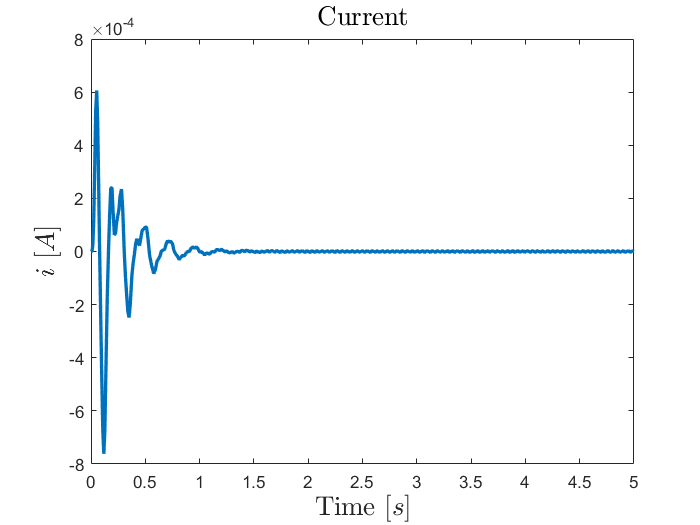

% Your solution goes here:
Ki = Ki2;
Ks = Ks2;
x_0 = [0 0 0 0 0 0 0.005]'; 
%[1 2   3     4   5     6     7  ]
%[i x1 x1_dot x2 x2_dot x3 x3_dot]

% Simulation
sim("myEmagModel");

% Plots
time = i.time;

% i
figure
plot(time,i.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Current',"FontSize",16, 'Interpreter','latex');


% u
figure
plot(time,u.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Input voltage',"FontSize",16, 'Interpreter','latex');

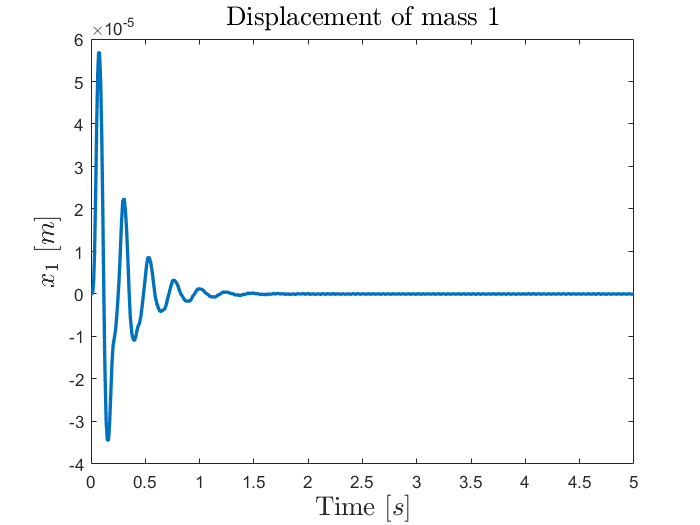


% x1
figure
plot(time,x1.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_1$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 1',"FontSize",16, 'Interpreter','latex');

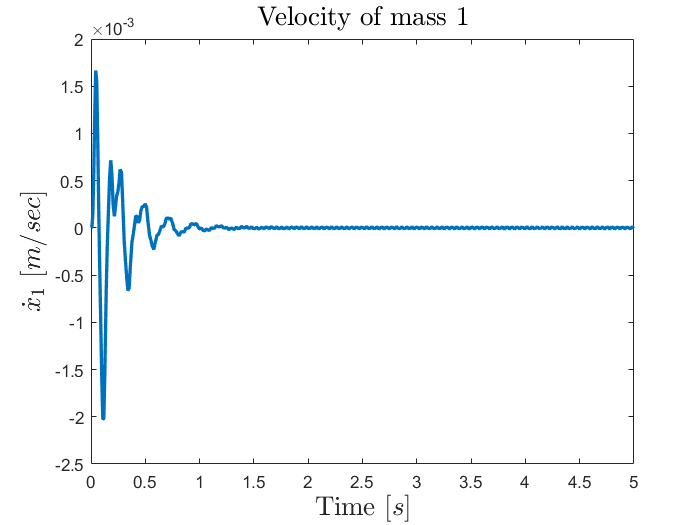


%x1_dot
figure
plot(time,x1d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 1',"FontSize",16, 'Interpreter','latex');

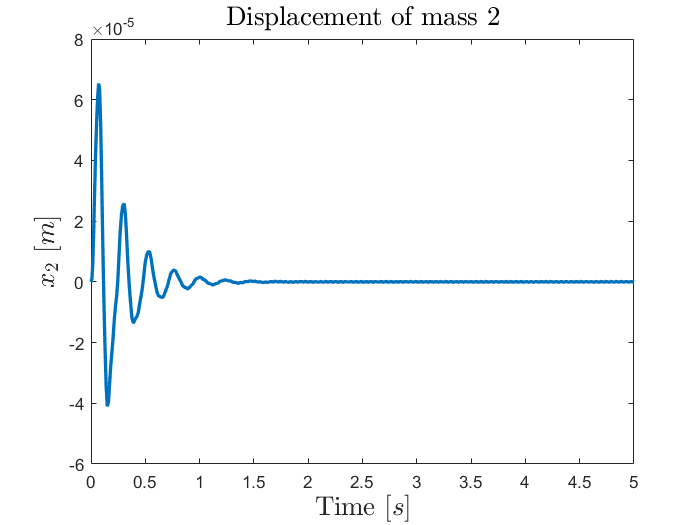


%x2
figure
plot(time,x2.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_2$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 2',"FontSize",16, 'Interpreter','latex');

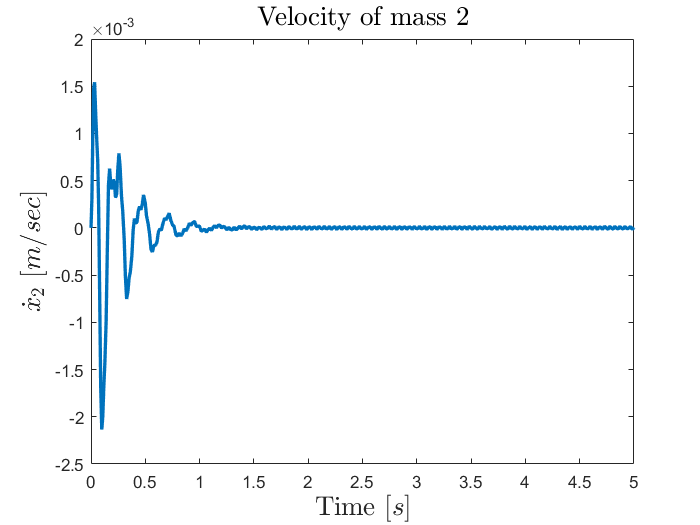


%x2_dot
figure
plot(time,x2d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 2',"FontSize",16, 'Interpreter','latex');

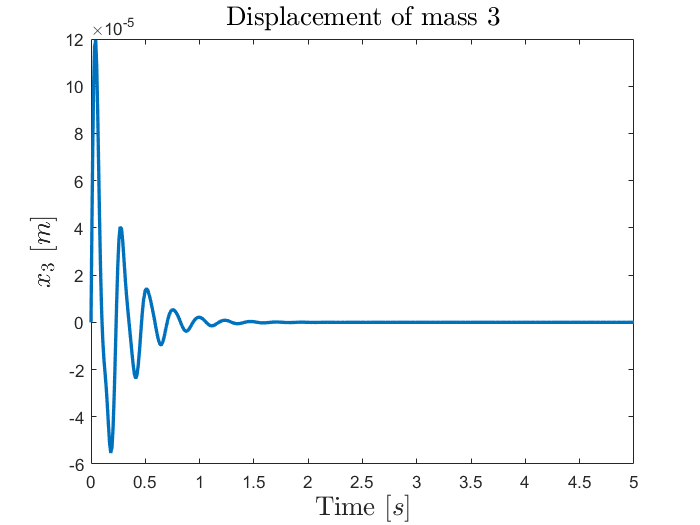


%x3
figure
plot(time,x3.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_3$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 3',"FontSize",16, 'Interpreter','latex');

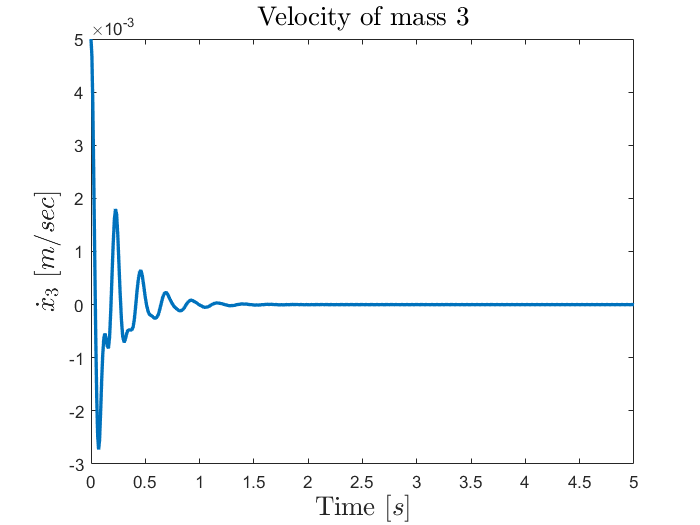


%x3_dot
figure
plot(time,x3d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 3',"FontSize",16, 'Interpreter','latex');

**Problem 6**

A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies.

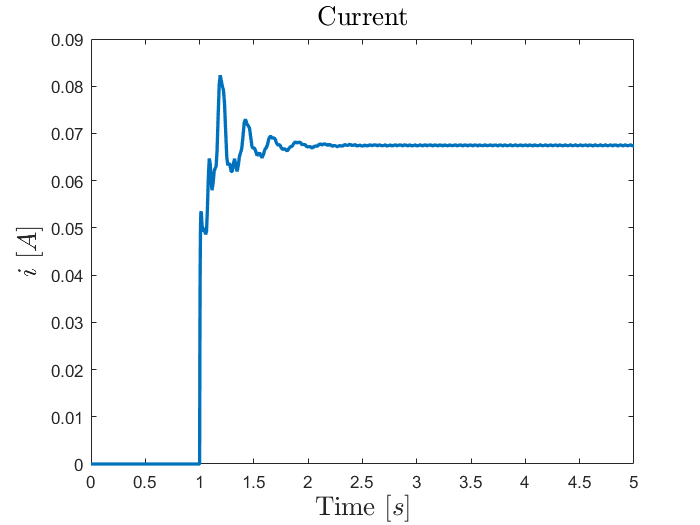

Ki = Ki2;
Ks = Ks2;
x_0 = [0 0 0 0 0 0 0]'; 
%[1 2   3     4   5     6     7  ]
%[i x1 x1_dot x2 x2_dot x3 x3_dot]

u_0 = 10;
% Simulation
sim("myEmagModel");
%sim("electroMagnetModel");

% Plots
time = i.time;

% i
figure
plot(time,i.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Current',"FontSize",16, 'Interpreter','latex');

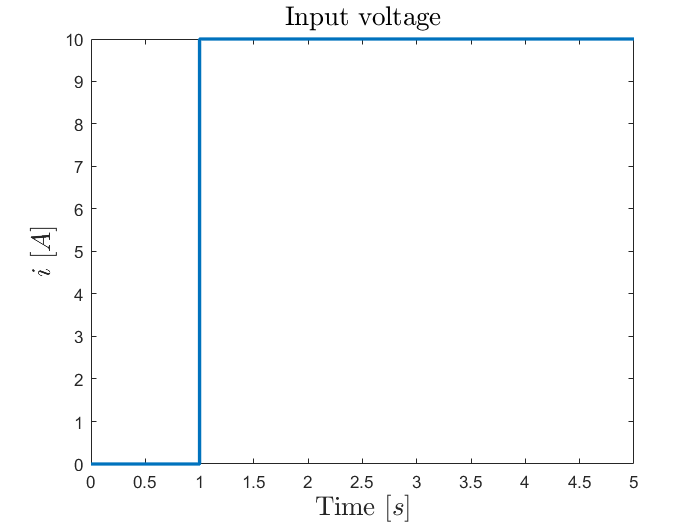


% u
figure
plot(time,u.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$i$ $[A]$',"FontSize",16, 'Interpreter','latex');
title('Input voltage',"FontSize",16, 'Interpreter','latex');

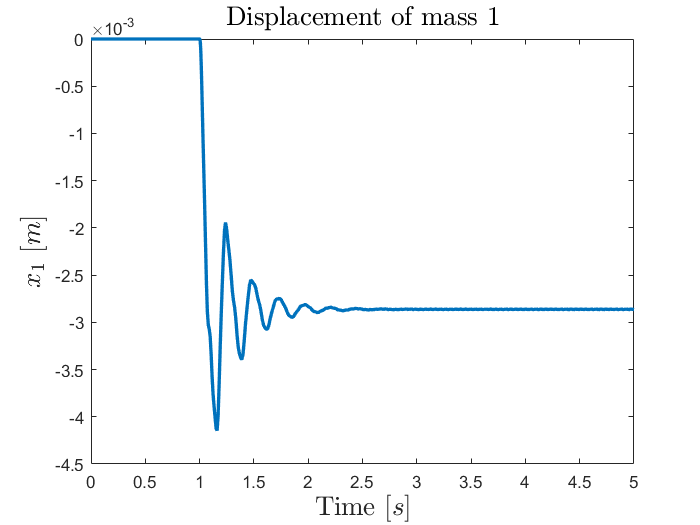


% x1
figure
plot(time,x1.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_1$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 1',"FontSize",16, 'Interpreter','latex');

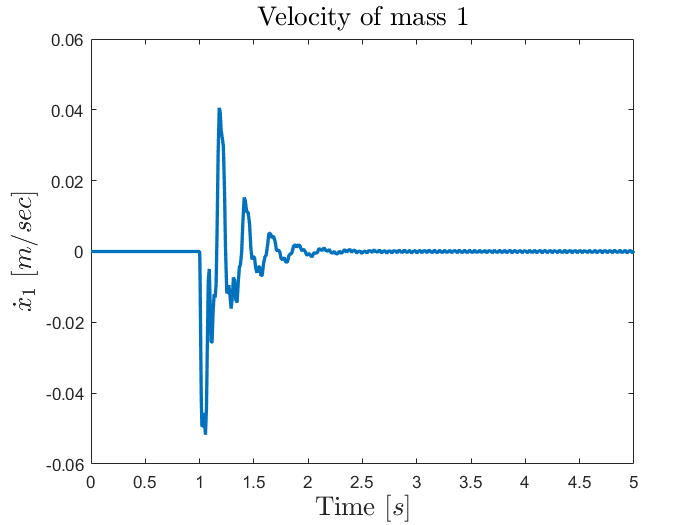


%x1_dot
figure
plot(time,x1d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_1$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 1',"FontSize",16, 'Interpreter','latex');

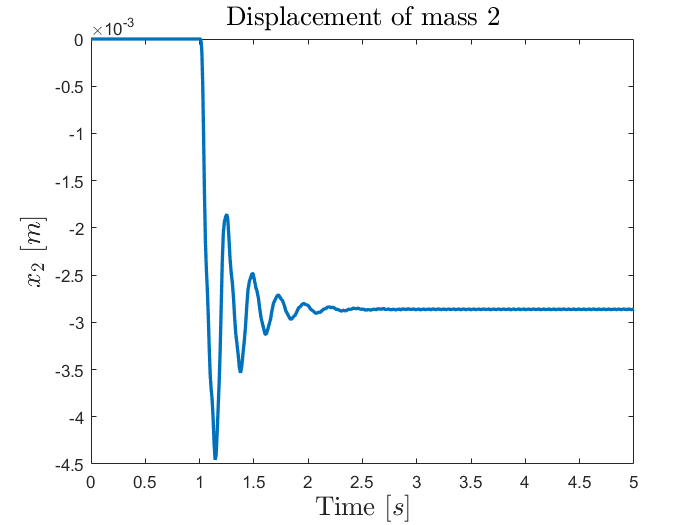


%x2
figure
plot(time,x2.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_2$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 2',"FontSize",16, 'Interpreter','latex');

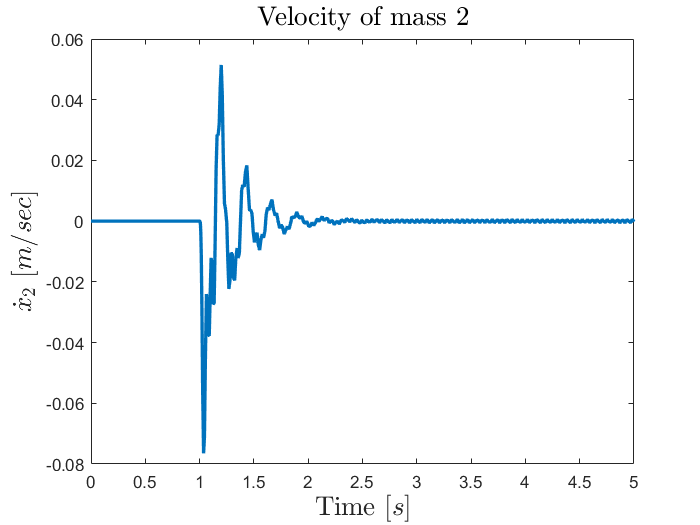


%x2_dot
figure
plot(time,x2d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_2$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 2',"FontSize",16, 'Interpreter','latex');

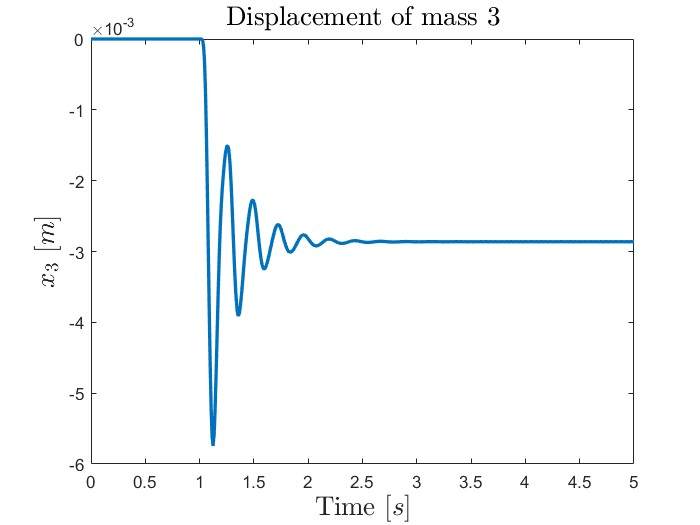


%x3
figure
plot(time,x3.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$x_3$ $[m]$',"FontSize",16, 'Interpreter','latex');
title('Displacement of mass 3',"FontSize",16, 'Interpreter','latex');

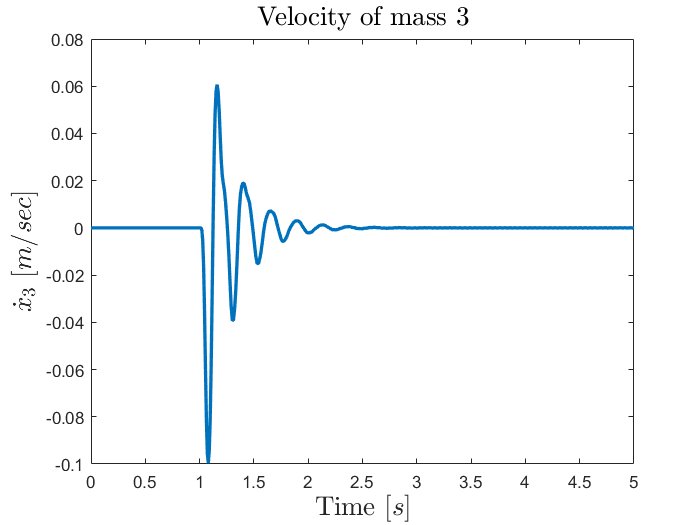


%x3_dot
figure
plot(time,x3d.signals.values, 'LineWidth',2);
xlabel('Time $[s]$','FontSize',16, 'Interpreter','latex');
ylabel('$\dot{x}_3$ $[m/sec]$',"FontSize",16, 'Interpreter','latex');
title('Velocity of mass 3',"FontSize",16, 'Interpreter','latex');